## **Part I - Producing forecasts from Coulomb stresses **

The functions described below produce forecasts of seismicity rate following a mainshock. In addition to the examples below, you can learn more about each function by calling "help d94", "help coulomb2forecast" etc.

The emphasis here is on simplicity and readability rather than performance. For more complex scenarios, a parallel code to calculate rate-state forecasts with heterogeneous background rate, complex receiver geometry and time-dependent stresses is available here: https://github.com/camcat/crs

According to eq. 12 in Dieterich (1994), the seismicity rate ***R*** at a time *t* after an instantaneous stress step is given by:

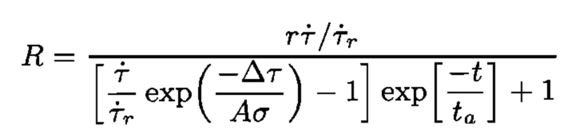                           (1)

where *r* is the background seismicity rate; *σ* the effective normal stress;   and    the shear stressing rate after and before the mainshock; *A* the rate-state parameter for direct effect; *ta *the aftershock decay time; *Δτ* the coseismic Coulomb stress change.

Here you will use Coulomb stress changes previously calculated in EPSy. First we set up required paths, and load stress changes:

path(path,'util')
set(0, 'DefaultLineLineWidth', 2);


inputfile='input/Norcia_Pizzi_2017/stresses_horiz_profile.txt';
cmb = loadinput(inputfile);

Loading input/Norcia_Pizzi_2017/stresses_horiz_profile.txt...
Found 2 header lines in file: input/Norcia_Pizzi_2017/stresses_horiz_profile.txt...
Field "lat" found at header line 1, column 2
Field "lon" found at header line 1, column 1
Field "depth" found at header line 1, column 3
Field "coulomb" found at header line 1, column 6


Then we specity time steps for the forecast, its start time, and rate-state parameters. Note that rate-state parameter A*σ *must have the same units as Coulomb stresses (here, kPa):


t0=1e-5; %start time (days)
ts=t0:1:300; %forecast time steps (days)

% set rate-state parameters (par = [r(1/days) asigma(kPa) ta(days)]:
r = 0.1; 
asig=10;
ta=1000;
rs_par = [r asig ta];

Finally, call the function **d94** to calculate seismicity rates (R) and cumulative number of events (C), and plot the result:

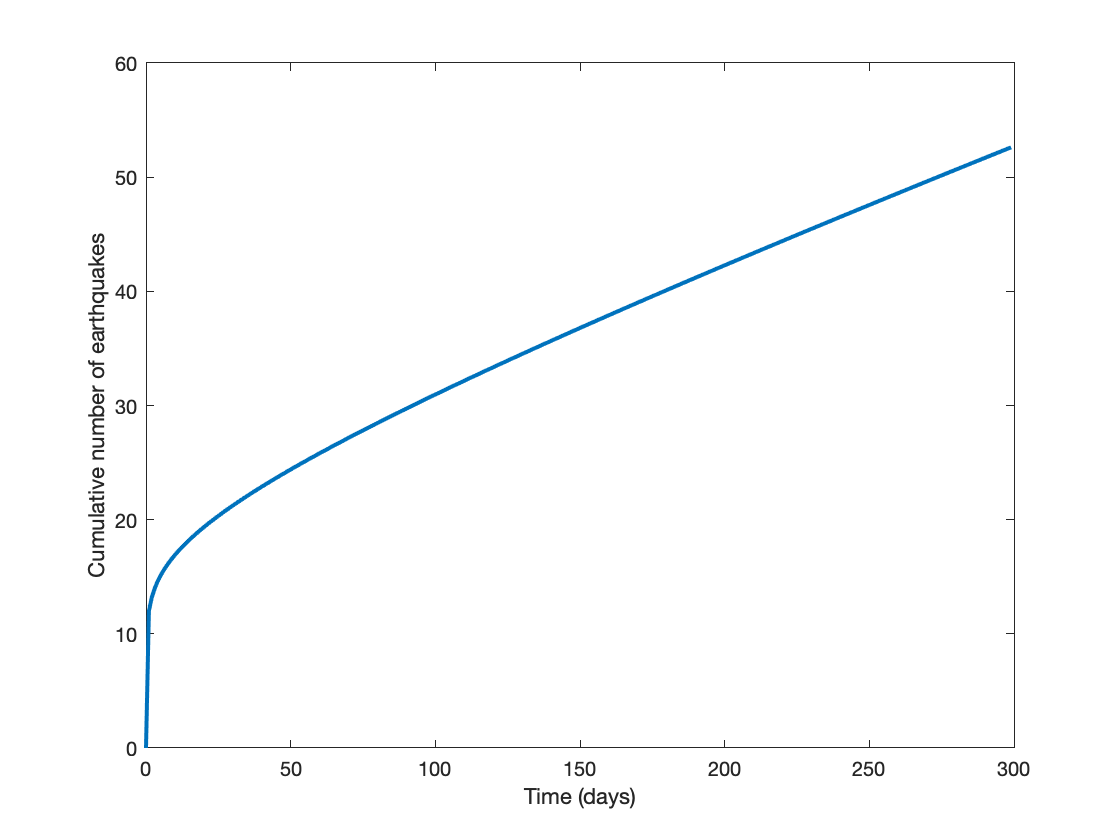


[R, C] = d94(ts, t0, rs_par, cmb);

figure
plot(ts,C);
xlabel('Time (days)');
ylabel('Cumulative number of earthquakes')

Note that the forecasted number of events is proportional to the background rate *r *(here 0.1 events/day). To get realistic earthquake probabilities, you will need to estimate the background rate by analyzing the seismicity catalog prio to the mainshock, or invert for it as we will do in Part II. If you are interested in the probability of large earthquakes, there may not be enough of them in the catalog to reliably estimate earthquake rate: instead, you can use the rate of smaller earthquakes and assume Gutemberg-Richter.

The function **d94** produces only a temporal forecast (i.e. seismicity rates are integrated over all calculation points). If instead you want to obtain a spatio-temporal forecast, use the function **coulomb2forecast.**

The function: **coulomb2forecast** reads an input file from calculated in EPSy  and calculates a forecast at specified time steps. It outputs seismicity rate and cumulative seismicity (nt = total number of earthquakes).

Here is a simple example: 


ts=1:10:300; %time steps (days)
[rate nt pos] = coulomb2forecast(inputfile, ts, t0, rs_par);

Loading input/Norcia_Pizzi_2017/stresses_horiz_profile.txt...
Found 2 header lines in file: input/Norcia_Pizzi_2017/stresses_horiz_profile.txt...
Field "lat" found at header line 1, column 2
Field "lon" found at header line 1, column 1
Field "depth" found at header line 1, column 3
Field "coulomb" found at header line 1, column 6
Calculating seismicity...


Let's plot the resuls:

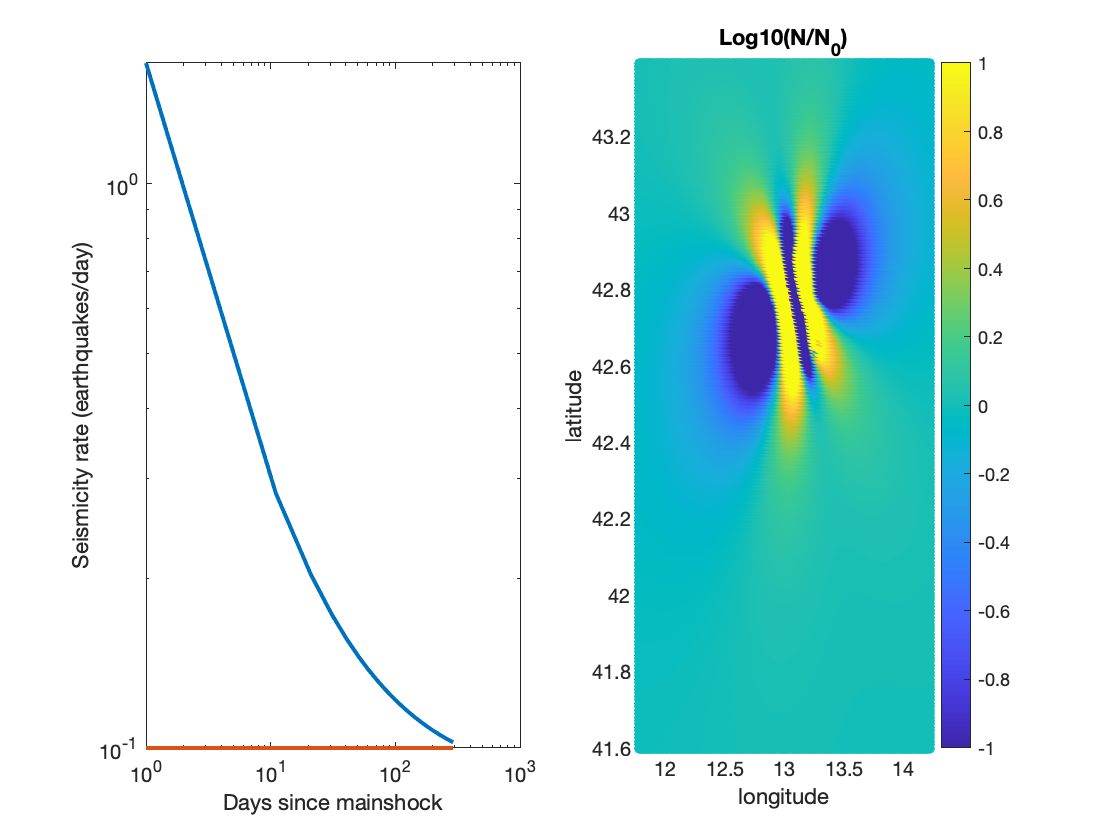


figure
subplot(1,2,1)
loglog(ts,sum(rate));
hold on
plot(ts([1 end]), r*[1 1])
xlabel('Days since mainshock')
ylabel('Seismicity rate (earthquakes/day)')

subplot(1,2,2)
n0=r*(ts(end)-t0)/length(cmb); %background number of events
scatter(pos.lon, pos.lat, 30, log10(nt(:,end)/n0), 'filled')
axis tight
colorbar
xlabel('longitude'); 
ylabel('latitude')
title('Log10(N/N_0)')
caxis([-1 1])

You can also use the function **coulomb2forecast** to produce an output forecast with the same format as the input, and use Kathryn's plotting scripts to make better maps.

### Forecast practice

- Change the values of rate-state parameters A*σ *, ta. How do forecasts change in each case?

- Starting from eq. 1 above, derive an expression for seismicity rates at short times (t << ta). Run the function **d94** with a single value of Coulomb stress change equal to a known fraction of A*σ, *for example* Δτ* =A*σ. *Plot it and check your result for t << ta. [Hint: use a log scale and plot normalized times (t/ta) and normalized seismicity rate (R/r). Use time steps on a log scale, e.g. ts=10.^[-4:0.01:2]*ta).

- The Coulomb stress map shows regions of positive and negative Coulomb stress change. However, seismicity rates integrated over the entire region are very high. Why?

- If you look at long periods of time (exceeding ta), is the seismicity rate ever lower than the background rate? If so, why?

## **Part II - Inverting for rate-state parameters**

Here we will fit rate-state parameters to the early part of an aftershock sequence and use them to predict future seismicity.

First we load an existing catalog, which is simply a list of earthquake times since the mainshock (days). Here this is done within the function **load_Norcia**, which reads the catalog developed by Tan et al., (2021) and converts it to days since the Norcia mainshock.

Since small events are missing from the catalog, it is important to make sure you only target events exceeding the completeness magnitude Mc. The latter can be estimated by finding the peak of the probability density function of earthquake magnitudes; see Mignan (2012) for a formal derivation.

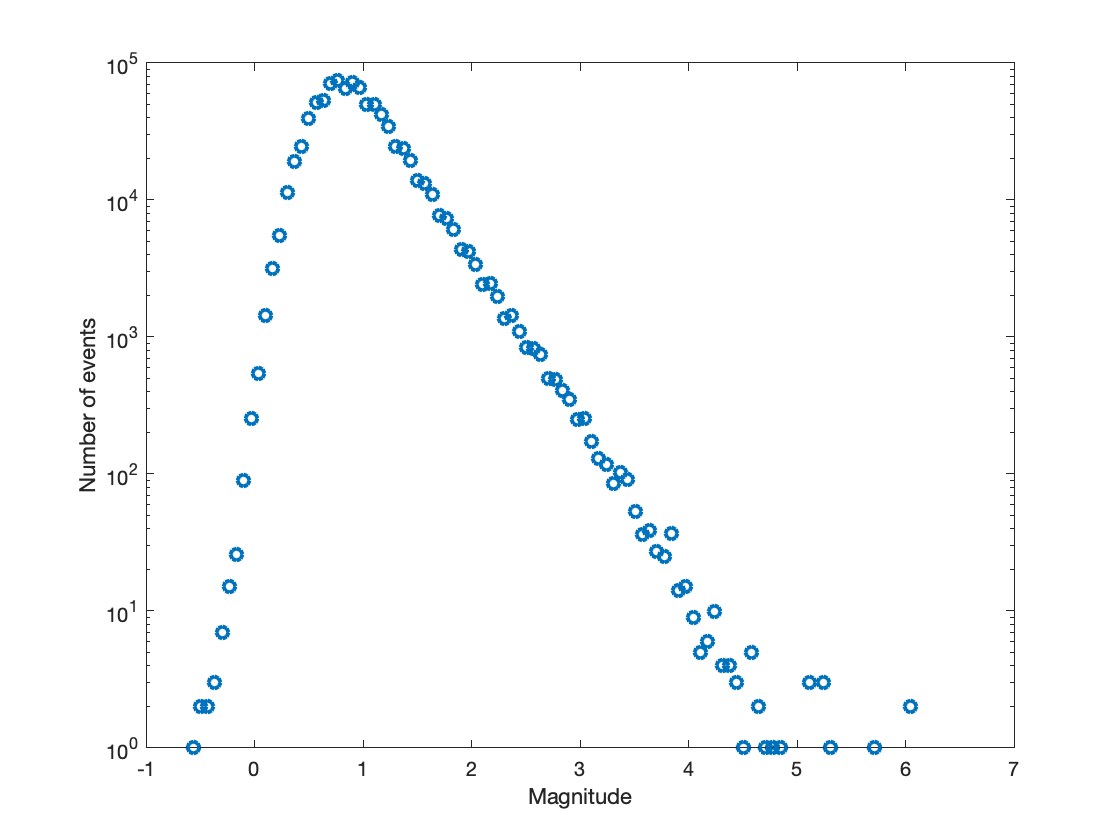

% Load catalog for region of interest and all magnitudes:
[cat mag lo la]=load_Norcia(-inf, [min(pos.lon) max(pos.lon)],[min(pos.lat) max(pos.lat)]);

% Check frequency-magnitude distribution:
[n,e] = histcounts(mag,100); %count no. of events vs. magnitude.
m = (e(1:end-1)+e(2:end))/2; %bin centers
figure
semilogy((e(1:end-1)+e(2:end))/2,n,'o');
xlabel('Magnitude');
ylabel('Number of events');

The plot shows a completeness magnitude around 1, so we choose a value of Mmin > 1.0 and select those events from the catalog. Here I am using a high Mmin to keep the cost of the parameter inversion low.

% Select events exceeding Mmin
Mmin=2.5;
cat=cat(mag>Mmin);

% Only keep first 100 days of aftershock sequence.
cat=cat(cat>0 & cat<100);


Next we use the function **ll_inversion.m** to find optimal rate-state parameters by maximizing the log-likelihood. Likelihood is the probability of a model parameter value given an observation, and maximum likelihood is a method for estimating model parameter vales based on maximizing the likelihood. For a formal derivation of the likelihood expression used in ll_inversion, see Zhuang et al. (2012).

The function ll_inversion requires the following inputs: earthquake catalog, coulomb stress changes, start and end times of the inversion period. In this example we will use the first 25 days of seismicity to fit rate-state parameters, and forecast seismicity for the following 50 days.

% Fit rate-state parameters:
tstart=cat(1);
tend=25;
[asigi, tai, ri] = ll_inversion(cat, cmb, tstart, tend);

Log-likelihood inversion with following parameters:
asig in range: [0.1 1000]
ta in range: [1 10000]
Taking 12 steps
asig=0.1, ta=1, sum(log(r))=2798.1201, ntot=697, ll=2101.1201
asig=0.1, ta=2.1544, sum(log(r))=2955.7382, ntot=697, ll=2258.7382
asig=0.1, ta=4.6416, sum(log(r))=3047.0892, ntot=697, ll=2350.0892
asig=0.1, ta=10, sum(log(r))=3075.0123, ntot=697, ll=2378.0123
asig=0.1, ta=21.5443, sum(log(r))=3074.6277, ntot=697, ll=2377.6277
asig=0.1, ta=46.4159, sum(log(r))=3069.5456, ntot=697, ll=2372.5456
asig=0.1, ta=100, sum(log(r))=3065.2689, ntot=697, ll=2368.2689
asig=0.1, ta=215.4435, sum(log(r))=3061.8923, ntot=697, ll=2364.8923
asig=0.1, ta=464.1589, sum(log(r))=3058.945, ntot=697, ll=2361.945
asig=0.1, ta=1000, sum(log(r))=3056.176, ntot=697, ll=2359.176
asig=0.1, ta=2154.4347, sum(log(r))=3053.4997, ntot=697, ll=2356.4997
asig=0.1, ta=4641.5888, sum(log(r))=3050.8909, ntot=697, ll=2353.8909
asig=0.1, ta=10000, sum(log(r))=3048.3361, ntot=697, ll=2351.3361
asig=0.21544, ta=1,

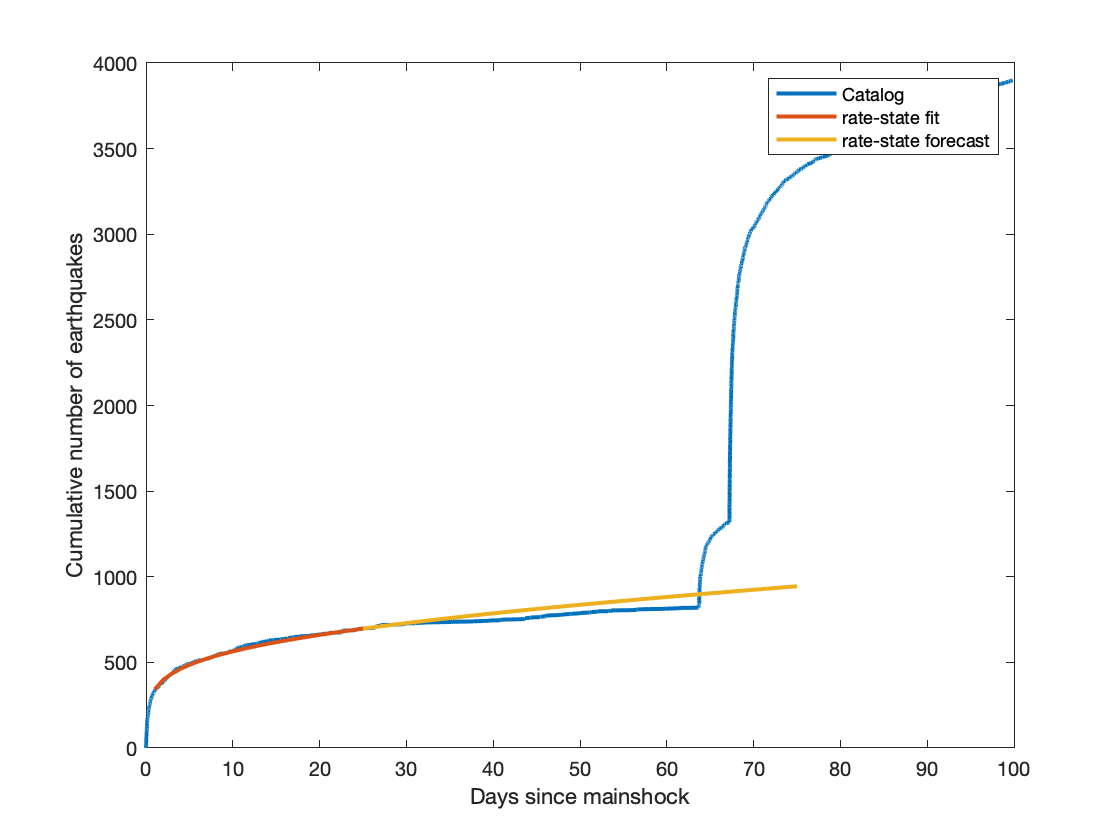


% Calculate forecast using optimal parameters:
ts1=0:1:tend; %forecast time steps (days)
ts2=tend:1:3*tend; %forecast time steps (days)
[R1, C1] = d94(ts1, cat(1), [ri, asigi, tai], cmb);
[R2, C2] = d94(ts2, cat(1), [ri, asigi, tai], cmb);

% Plot catalog and forecast:
figure
plot(cat, 1:length(cat));
hold on;
plot(ts1,C1);
plot(ts2,C2);
xlabel('Days since mainshock')
ylabel('Cumulative number of earthquakes')
legend({'Catalog','rate-state fit','rate-state forecast'})

**Notes:**

- This function only fits the temporal forecast. It is also possible to fit a spatio-temporal forecast, but this is sensitive to the spatial distribution of background seismicity as well as the choice of receiver fault orientation and the geometrical complexity of the underlying fault system (see e.g. Cattania et al., 2014).

- You can also specify additional options in ll_inversion, including the range of rate-state parameters and the number of steps in the grid search. If the estimate takes too long, try reducing the number of steps; if it's not a good fit, try increasing it.

### Catalog Practice

Look at the frequency-magnitude distribution immediately after the mainshock (e.g., the first 10 days) and at a later time far from any mainshocks (e.g. between 250-300 days).  

- How does the completeness magnitude change? Why?

- How do you think this effect may bias the estimation of rate-state parameters?

## References

Dieterich, J. (1994), A constitutive law for rate of earthquake production and its application to earthquake clustering, *J. Geophys. Res.*, 99( B2), 2601– 2618, doi:[10.1029/93JB02581](https://doi.org/10.1029/93JB02581).

Zhuang, J., D. Harte, M.J. Werner, S. Hainzl, and S. Zhou (2012), Basic models of seismicity: temporal models, Community Online Resource for Statistical Seismicity Analysis, doi:10.5078/corssa-79905851. Available at http://www.corssa.org.

Cattania, C., Hainzl, S., Wang, L., Roth, F., and Enescu, B. (2014), Propagation of Coulomb stress uncertainties in physics-based aftershock models, *J. Geophys. Res. Solid Earth*, 119, 7846– 7864, doi:[10.1002/2014JB011183](https://doi.org/10.1002/2014JB011183).

Tan, Yen Joe, Waldhauser, Felix, & Ellsworth, William. (2021). Machine-Learning-Based High-Resolution Earthquake Catalog For the 2016-2017 Central Italy Sequence [Data set]. Zenodo. https://doi.org/10.5281/zenodo.4662870

Mignan, A., J. Woessner (2012), Estimating the magnitude of completeness for earthquake catalogs, Community Online Resource for Statistical Seismicity Analysis, doi:10.5078/corssa-00180805. Available at http://www.corssa.org. 